# Deep Learning HW1

Akwasi Darkwah Akwaboah

02/20/2021

## Import Data

clear all
close all
load YaleB_32x32.mat

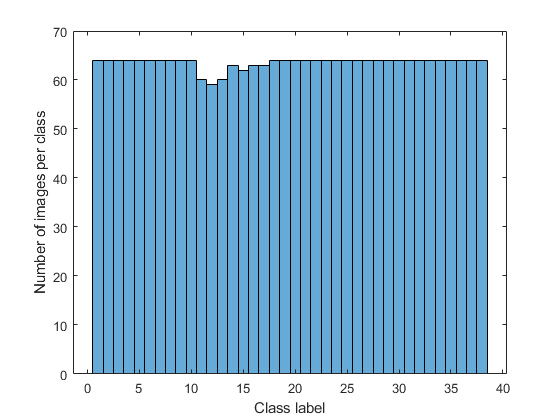

%Data statistics
histogram(gnd)
xlabel('Class label')
ylabel('Number of images per class')
set(gcf, 'PaperPosition', [0 0 4 3]);
print(gcf, '-dpng', ['./Data_hist.png']);

## Train-Test

- Nearest neighbor algorithm, k = 1, p = 2 (euclidean)

Cl_Err_Store_NN = zeros(1,5);
i = 0;
for m = 10:10: 50
    rng(1000)
    k = 1;%k-NN: # of nearest neighbors
    p = 2; %l-p norm (type of norm)
    % m = 10
    %function data_split(m, data) can also be applied in the CV
    [fea_train, gnd_train, fea_test, gnd_test] = data_split(fea, gnd, m);
    votes_final = kNN_predict(fea_train, gnd_train, fea_test, p, k);
    Cl_Err = KNN_score(votes_final, gnd_test);
    Cl_Err
    Cl_Err_Store_NN(m/10) = Cl_Err;
end

Cl_Err = 54.2281

Cl_Err = 42.3821

Cl_Err = 36.1068

Cl_Err = 28.7472

Cl_Err = 25.2918


save('Q1_NN_m10_50.mat', "Cl_Err_Store_NN")

Cl_Err_Store_NN

Cl_Err_Store_NN =    54.2281   42.3821   36.1068   28.7472   25.2918


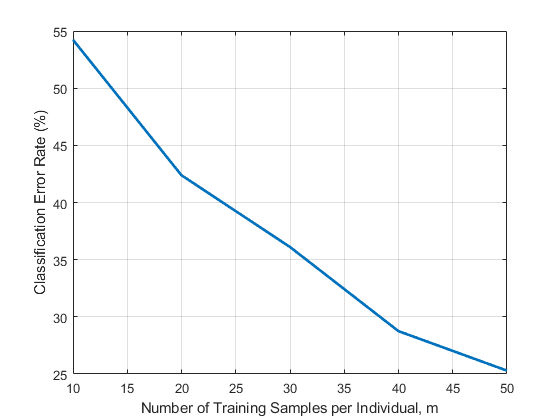

close all
figure(1)
m = 10:10: 50;
plot(m, Cl_Err_Store_NN, 'LineWidth', 2)
xlabel('Number of Training Samples per Individual, m')
ylabel('Classification Error Rate (%)')
grid on
set(gcf, 'PaperPosition', [0 0 4 3]);
print(gcf, '-dpng', ['./Q1_NN_m10_50.png']);


a = 1;
Cl_Err_Store_kNN = zeros(4,5);
for k = [1 2 3 5 10] %k-NN: # of nearest neighbors
    b = 1;
    for m = 10:10: 50
        rng(1000)
        p = 2; %l-p norm (type of norm)
        % m = 10
        %function data_split(m, data) can also be applied in the CV
        [fea_train, gnd_train, fea_test, gnd_test] = data_split(fea, gnd, m);
        votes_final = kNN_predict(fea_train, gnd_train, fea_test, p, k);
        Cl_Err = KNN_score(votes_final, gnd_test);
        Cl_Err
        Cl_Err_Store_kNN(a, b) = Cl_Err;   
        b = b + 1;
    end
    a = a + 1;
    fprintf('___________________________')
end

Cl_Err = 54.2281

Cl_Err = 42.3821

Cl_Err = 36.1068

Cl_Err = 28.7472

Cl_Err = 25.2918

___________________________

Cl_Err = 54.2281

Cl_Err = 42.3821

Cl_Err = 36.1068

Cl_Err = 28.7472

Cl_Err = 25.2918

___________________________

Cl_Err = 55.9980

Cl_Err = 44.0145

Cl_Err = 37.0487

Cl_Err = 29.4183

Cl_Err = 26.0700

___________________________

Cl_Err = 61.1111

Cl_Err = 47.1584

Cl_Err = 39.3250

Cl_Err = 32.1029

Cl_Err = 27.0428

___________________________

Cl_Err = 67.9449

Cl_Err = 54.2926

Cl_Err = 42.6217

Cl_Err = 34.7875

Cl_Err = 31.1284

___________________________

save('Q1_NN_m10_50_k2_10.mat', 'Cl_Err_Store_kNN')

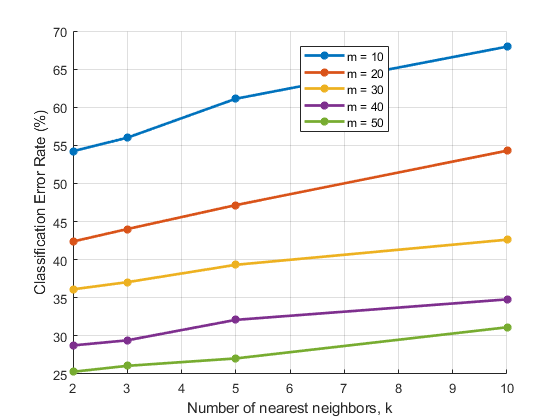

close all
hold off
k = [2 3 5 10];
figure(1)
grid on
hold on
for i = 1:5
    plot(k, Cl_Err_Store_kNN(2:end, i), '-*', 'LineWidth', 2)
    xlabel('Number of nearest neighbors, k')
    ylabel('Classification Error Rate (%)')
end
legend({'m = 10','m = 20','m = 30','m = 40','m = 50'}, 'Location',"best")
grid on
set(gcf, 'PaperPosition', [0 0 4 3]);
print(gcf, '-dpng', ['./mk_sweep_kNN.png']);

Cl_Err_Store_kNN

Cl_Err_Store_kNN =    54.2281   42.3821   36.1068   28.7472   25.2918
   54.2281   42.3821   36.1068   28.7472   25.2918
   55.9980   44.0145   37.0487   29.4183   26.0700
   61.1111   47.1584   39.3250   32.1029   27.0428
   67.9449   54.2926   42.6217   34.7875   31.1284


## Misclassified samples

Cl_Err_Store_NN = zeros(1,5);
i = 0;
m = 30;
rng(1000)
k = 8;%k-NN: # of nearest neighbors
p = 2; %l-p norm (type of norm)
% m = 10
%function data_split(m, data) can also be applied in the CV
[fea_train, gnd_train, fea_test, gnd_test] = data_split(fea, gnd, m);
[votes_final, votes_idx] = kNN_predict(fea_train, gnd_train, fea_test, p, k);
Cl_Err = KNN_score(votes_final, gnd_test);
Cl_Err

Cl_Err = 41.2088

Cl_Err_Store_NN(m/10) = Cl_Err;

Miss_Class_idx = [];
Miss_Class_label = [];
for i = 1:length(votes_final)
    if votes_final(i) ~= gnd_test(i)
        Miss_Class_idx = [Miss_Class_idx, i];
        Miss_Class_label = [Miss_Class_label, votes_final(i)];
    end
end

Miss_Class_idx

Miss_Class_idx =      3    10    12    13    17    18    19    20    26    27    29    30    31    33    34    43    48    52    60    63    64    65    66    68    71    73    75    78    80    82    83    84    85    86    87    89    92    94    95    97    99   100   101   102   107   111   113   115   116   119


rng(100)
shuffle = @(x) x(randperm(length(x)));
mis_shf_idx = shuffle(Miss_Class_idx)

mis_shf_idx =         1000         321          17          75         760         780        1085          82         729        1201         102         301         592         342         589         898        1064         949        1100         514          87         993         348         144         718         782         895         759          94         812        1015         597        1149         699         931        1146         824         511        1209         594         843         479         568        1186        1210         218         337        1160         813         213


% mis_shf_idx = Miss_Class_idx
% k = ;%k-NN: # of nearest neighbors
% p = 2; %l-p norm (type of norm)

[votes_fin, v_idx] = kNN_predict(fea_train, gnd_train, fea_test(mis_shf_idx(1)), p, k)

votes_fin = 38

v_idx =         1126        1023        1108        1062         766          98         589         137


gnd_train(v_idx)

ans =     38
    35
    37
    36
    26
     4
    20
     5


figure()
plt_cnt = k;
mis_shf_idx(1)

ans = 1000

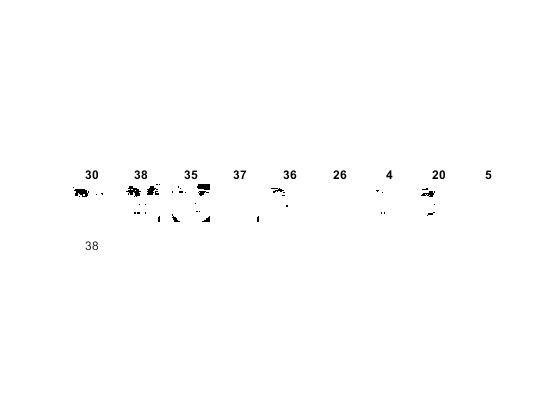

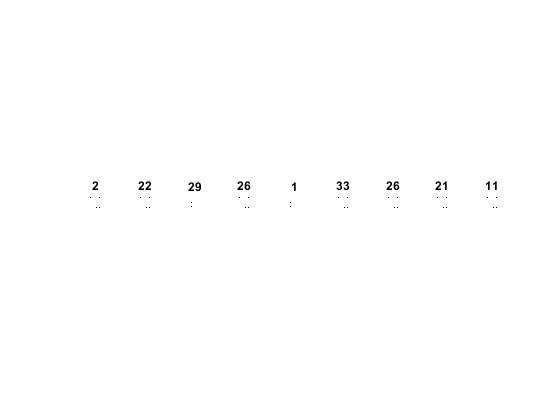

plt_var = fea_test(mis_shf_idx(1),:);
plt_var = reshape(plt_var, 32, 32);
subplot(191)
imshow(plt_var )
lab = num2str(gnd_test(mis_shf_idx(1)));
title(lab)
xlabel(votes_fin)
for i = 1:plt_cnt
    plt_idx = v_idx(i);
    plt_var = fea_test(plt_idx,:);
    plt_var = reshape(plt_var, 32, 32);
    subplot(191 + i)
    imshow(plt_var)
    lab = num2str(gnd_train(plt_idx));
    title(lab)
end
set(gcf, 'PaperPosition', [0 0 9 3]);
print(gcf, '-dpng', ['./missed_class8.png']);

## Q3 

exploring p

Cl_Err_Store_pNN = zeros(1,4);
i = 1;
for p = [1 3 5 10]
    rng(1000)
    k = 3;%k-NN: # of nearest neighbors
    m = 30; %l-p norm (type of norm)
    %function data_split(m, data) can also be applied in the CV
    [fea_train, gnd_train, fea_test, gnd_test] = data_split(fea, gnd, m);
    [votes_final, ~] = kNN_predict(fea_train, gnd_train, fea_test, p, k);
    Cl_Err = KNN_score(votes_final, gnd_test);
    Cl_Err
    Cl_Err_Store_pNN(i) = Cl_Err;
    i = i + 1;
end

Cl_Err = 40.9733


save('Q1_NN_p1_10.mat', 'Cl_Err_Store_pNN')

Cl_Err_Store_pNN

close all
figure(1)
p = [1 3 5 10];
plot(p, Cl_Err_Store_pNN(1:4), 'LineWidth', 2)
xlabel('order of distance metric -- p')
ylabel('Classification Error Rate (%)')
grid on
set(gcf, 'PaperPosition', [0 0 4 3]);
print(gcf, '-dpng', ['./Q1_NN_p1_10.png']);


Q4

LBP_array = [];
for i = 1:length(gnd)
    LBP_i = extractLBPFeatures(reshape(fea(i,:), 32, 32));
    LBP_array = [LBP_array; LBP_i];
end


HOG_array = [];
for i = 1:length(gnd)
    HOG_i = extractHOGFeatures(reshape(fea(i,:), 32, 32));
    HOG_array = [HOG_array; HOG_i];
end


LBP

Cl_Err_Store_pNN_LBP = zeros(1,2);
i = 1;
for p = [1 2]
    rng(1000)
    k = 3;%k-NN: # of nearest neighbors
    m = 30; %l-p norm (type of norm)
    %function data_split(m, data) can also be applied in the CV
    [fea_train, gnd_train, fea_test, gnd_test] = data_split(LBP_array, gnd, m);
    [votes_final, ~] = kNN_predict(fea_train, gnd_train, fea_test, p, k);
    Cl_Err = KNN_score(votes_final, gnd_test);
    Cl_Err
    Cl_Err_Store_pNN_LBP(i) = Cl_Err;
    i = i + 1;
end

Cl_Err = 85.2433

Cl_Err = 85.2433


save('Q1_NN_p1_10_LBP.mat', "Cl_Err_Store_pNN_LBP")


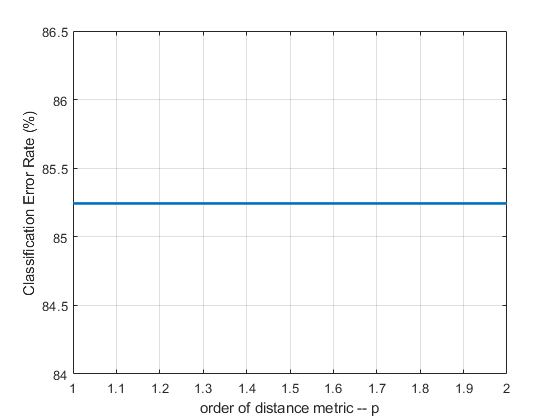

close all
figure(1)
p = [1 2];
plot(p, Cl_Err_Store_pNN_LBP, 'LineWidth', 2)
xlabel('order of distance metric -- p')
ylabel('Classification Error Rate (%)')
grid on
set(gcf, 'PaperPosition', [0 0 4 3]);
print(gcf, '-dpng', ['./Q1_NN_p1_10_LBP.png']);

HOG

Cl_Err_Store_pNN_HOG = zeros(1,2);
i = 1;
for p = [1 2]
    rng(1000)
    k = 3;%k-NN: # of nearest neighbors
    m = 30; %l-p norm (type of norm)
    %function data_split(m, data) can also be applied in the CV
    [fea_train, gnd_train, fea_test, gnd_test] = data_split(HOG_array, gnd, m);
    [votes_final, ~] = kNN_predict(fea_train, gnd_train, fea_test, p, k);
    Cl_Err = KNN_score(votes_final, gnd_test);
    Cl_Err
    Cl_Err_Store_pNN_HOG(i) = Cl_Err;
    i = i + 1;
end

Cl_Err = 54.9451

Cl_Err = 54.2386


save('Q1_NN_p1_10_HOG.mat', "Cl_Err_Store_pNN_HOG")


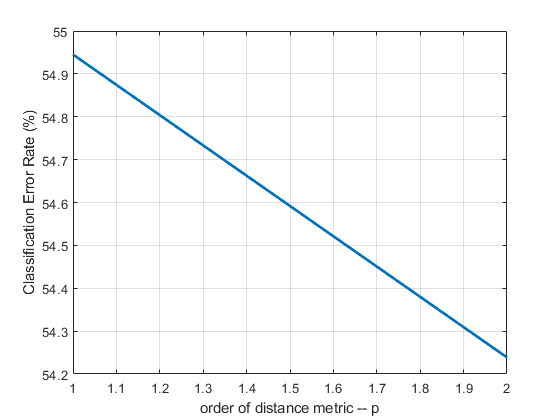

close all
figure(1)
p = [1 2];
plot(p, Cl_Err_Store_pNN_HOG, 'LineWidth', 2)
xlabel('order of distance metric -- p')
ylabel('Classification Error Rate (%)')
grid on
set(gcf, 'PaperPosition', [0 0 4 3]);
print(gcf, '-dpng', ['./Q1_NN_p1_10_HOG.png']);

Pixel Intensities

Cl_Err_Store_pNN_Pix = zeros(1,2);
i = 1;
for p = [1 2]
    rng(1000)
    k = 3;%k-NN: # of nearest neighbors
    m = 30; %l-p norm (type of norm)
    %function data_split(m, data) can also be applied in the CV
    [fea_train, gnd_train, fea_test, gnd_test] = data_split(fea, gnd, m);
    [votes_final, ~] = kNN_predict(fea_train, gnd_train, fea_test, p, k);
    Cl_Err = KNN_score(votes_final, gnd_test);
    Cl_Err
    Cl_Err_Store_pNN_Pix(i) = Cl_Err;
    i = i + 1;
end

Cl_Err = 40.9733

Cl_Err = 37.0487


save('Q1_NN_p1_10_Pix.mat', "Cl_Err_Store_pNN_Pix")

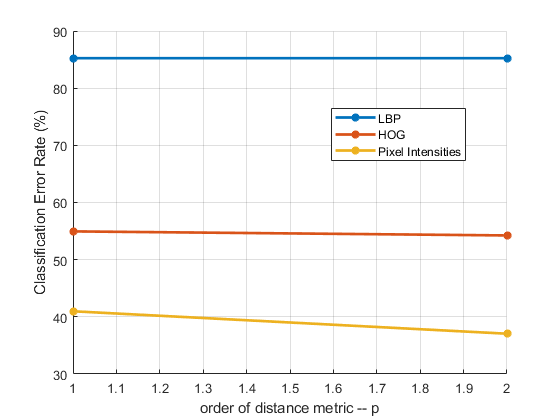

close all
figure(1)
hold on
p = [1 2];
plot(p, Cl_Err_Store_pNN_LBP, '-*', 'LineWidth', 2)
plot(p, Cl_Err_Store_pNN_HOG, '-*', 'LineWidth', 2)
plot(p, Cl_Err_Store_pNN_Pix, '-*', 'LineWidth', 2)
xlabel('order of distance metric -- p')
ylabel('Classification Error Rate (%)')
legend({'LBP', 'HOG', 'Pixel Intensities'}, 'Location',"best")
grid on
set(gcf, 'PaperPosition', [0 0 4 3]);
print(gcf, '-dpng', ['./Q1_NN_p1_10_All3.png']);
hold off

### 2.2 Validation

rng(1000)
[fea_test, gnd_test, fea_train, gnd_train] = data_split(fea, gnd, 20);
[fea_val, gnd_val, fea_train2, gnd_train2] = data_split(fea_train, gnd_train, 10);

a = 1;
Cl_Err_Store_pkNN = zeros(10,10);
for k = 1:10 %k-NN: # of nearest neighbors --row
    b = 1;
    for p = 1:10 %l-p norm (type of norm) --colum
        rng(1000)
        [votes_final, ~] = kNN_predict(fea_train2, gnd_train2, fea_val, p, k);
        Cl_Err = KNN_score(votes_final, gnd_val);
        Cl_Err
        Cl_Err_Store_pkNN(a, b) = Cl_Err;   
        b = b + 1;
    end
    a = a + 1;
    fprintf('___________________________')
end

Cl_Err = 39.7368

Cl_Err = 33.4211

Cl_Err = 30.5263

Cl_Err = 27.1053

Cl_Err = 27.3684

Cl_Err = 28.4211

Cl_Err = 30

Cl_Err = 31.3158

Cl_Err = 31.3158

Cl_Err = 31.8421

___________________________

Cl_Err = 39.7368

Cl_Err = 33.4211

Cl_Err = 30.5263

Cl_Err = 27.1053

Cl_Err = 27.3684

Cl_Err = 28.4211

Cl_Err = 30

Cl_Err = 31.3158

Cl_Err = 31.3158

Cl_Err = 31.8421

___________________________

Cl_Err = 38.4211

Cl_Err = 33.9474

Cl_Err = 30.7895

Cl_Err = 28.1579

Cl_Err = 31.0526

Cl_Err = 32.3684

Cl_Err = 34.7368

Cl_Err = 36.5789

Cl_Err = 36.8421

Cl_Err = 37.6316

___________________________

Cl_Err = 39.4737

Cl_Err = 34.4737

Cl_Err = 30.2632

Cl_Err = 28.6842

Cl_Err = 32.3684

Cl_Err = 35.5263

Cl_Err = 36.0526

Cl_Err = 37.8947

Cl_Err = 38.4211

Cl_Err = 38.1579

___________________________

Cl_Err = 38.9474

Cl_Err = 34.7368

Cl_Err = 32.3684

Cl_Err = 29.7368

Cl_Err = 33.1579

Cl_Err = 36.8421

Cl_Err = 38.4211

Cl_Err = 40.2632

Cl_Err = 39.7368

Cl_Err = 40

___________________________

Cl_Err = 41.5789

Cl_Err = 35.5263

Cl_Err = 34.7368

Cl_Err = 32.3684

Cl_Err = 34.2105

Cl_Err = 36.0526

Cl_Err = 38.4211

Cl_Err = 39.7368

Cl_Err = 40.5263

Cl_Err = 41.5789

___________________________

Cl_Err = 41.5789

Cl_Err = 37.6316

Cl_Err = 34.4737

Cl_Err = 33.4211

Cl_Err = 36.8421

Cl_Err = 38.1579

Cl_Err = 39.4737

Cl_Err = 41.0526

Cl_Err = 42.8947

Cl_Err = 44.2105

___________________________

Cl_Err = 42.1053

Cl_Err = 37.8947

Cl_Err = 33.6842

Cl_Err = 33.9474

Cl_Err = 36.0526

Cl_Err = 38.6842

Cl_Err = 40.2632

Cl_Err = 42.3684

Cl_Err = 45.5263

Cl_Err = 46.0526

___________________________

Cl_Err = 42.6316

Cl_Err = 38.4211

Cl_Err = 35

Cl_Err = 35.5263

Cl_Err = 37.8947

Cl_Err = 39.4737

Cl_Err = 42.6316

Cl_Err = 43.4211

Cl_Err = 45.2632

Cl_Err = 47.1053

___________________________

Cl_Err = 45

Cl_Err = 38.4211

Cl_Err = 36.5789

Cl_Err = 35.2632

Cl_Err = 39.2105

Cl_Err = 40.2632

Cl_Err = 41.5789

Cl_Err = 43.6842

Cl_Err = 46.0526

Cl_Err = 48.1579

___________________________

save('Q1_NN_pk_val.mat', 'Cl_Err_Store_pkNN')

mn = min(Cl_Err_Store_pkNN, [], 'all')

mn = 39.7368

[min_loc, I] = find(Cl_Err_Store_pkNN == mn)

min_loc =      1
     2


I =      1
     1


function [x_train, y_train, x_test, y_test] = data_split(X, Y, m)
    idx_train = [];
    offset = 0;
    for i = 1:38
        idx_k = find(Y==i);
        idx_m_sel = offset + randperm(length(idx_k), m);
        idx_train = [idx_train, idx_m_sel];
        offset = idx_k(end);
    end
    % length(unique(idx_train))
    cnt = [1:length(Y)];
    idx_test = setdiff(cnt, idx_train);
    % length(unique(idx_test))
    
    x_train = X(idx_train, :);
    y_train = Y(idx_train);
    x_test = X(idx_test, :);
    y_test = Y(idx_test);
end

function  [votes_final, votes_idx] = kNN_predict(x_train, y_train, x_test, p, k)
    [r, ~] = size(x_test);
    votes_idx = zeros(r,k);
    k_dists = zeros(r, k);
    votes = zeros(r,k);
    votes_final = zeros(r, 1);
    dist_final = zeros(r, 1);
    
    for j = 1:r
        res = vecnorm((x_train - x_test(j,:)), p, 2);
        [k_dists(j,:), I] = mink(res, k);
        votes_idx(j, :) = I;
        votes(j, :) = y_train(I);
        [~, ~, c] = mode(y_train(I));
        mode_n = c{1};
        mode_idx = [];
        for i = 1:length(mode_n) % handles when there is a tie
            [~, mode_idx_i] = find(votes(j,:)==mode_n(i));
            mode_idx = [mode_idx, mode_idx_i];        
        end
        [dist_final(j), ~] = min(k_dists(j, mode_idx)); %choose vote with minimum residual
        [~, md_idx] = find(k_dists(j,:) == dist_final(j));
        votes_final(j) = votes(j, md_idx(1));
    end
%     votes
%     votes_final
%     k_dists
%     dist_final
%     histogram(votes_final);
end

function Err = KNN_score(votes, y_test)
    Miss_Class_idx = [];
    Miss_Class_label = [];
    for i = 1:length(votes)
        if votes(i) ~= y_test(i)
            Miss_Class_idx = [Miss_Class_idx, i];
            Miss_Class_label = [Miss_Class_label, votes(i)];
        end
    end
    
    Err = (length(Miss_Class_idx)/length(y_test))*100;
    
%     Miss_Class_label;
%     y_test(Miss_Class_idx)';
end
